#### Q5

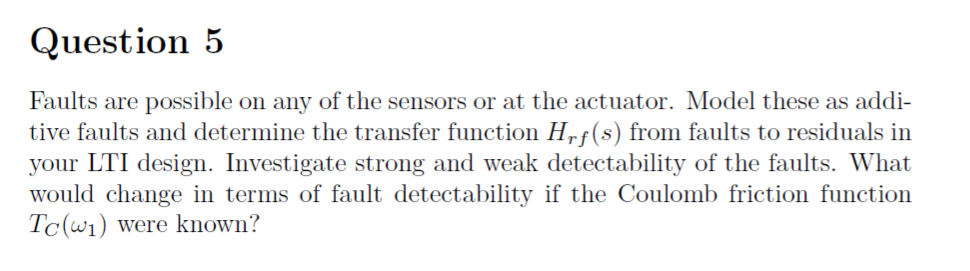

clear all
close all;
clc;

load('Q3_Q4_Q5.mat')
B(2,1)=1/J_1;


%Fauls present in any of the sensors or at the actuator:
        %f=[f_u;f_y1;f_y2;f_y3]

Fx=[B zeros(size(A,1),3)];      % only present f_u
Fy=[zeros(size(C,1),1) eye(3)]; %only present f_y1;f_y2;f_y3

%Hyf:

Hyf=simplify(C*inv(s*eye(size(A,1))-A)*Fx+Fy);

%Hrf:

Hrf=Vry*Hyf

$$Hrf = \begin{array}{l} \left(\begin{array}{cccc} 0 & -\frac{k_{1}\,\left(J_{3}\,s^{2}+b_{3}\,s+k_{2}\right)}{\sigma_{1}} & 1 & 0\\ 0 & -\frac{k_{1}\,k_{2}}{\sigma_{1}} & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=k_{1}\,k_{2}+b_{2}\,k_{2}\,s+b_{3}\,k_{1}\,s+b_{3}\,k_{2}\,s+J_{2}\,J_{3}\,s^{4}+J_{2}\,b_{3}\,s^{3}+J_{3}\,b_{2}\,s^{3}+J_{2}\,k_{2}\,s^{2}+J_{3}\,k_{1}\,s^{2}+J_{3}\,k_{2}\,s^{2}+b_{2}\,b_{3}\,s^{2} \end{array}$$


%Strong and weak detectability for each fault:

%Weak detectability: 

for i=1:4
    if(rank([Hyd Hyf(:,i)])>rank(Hyd))
        if subs(F*[Hyf(:,i); 0], s, 0) == 0
            fprintf('Fault %d is weak detectable\n',i)
        else
            fprintf('Fault %d is strongly detectable\n',i)
        end
    else
        fprintf('Fault %d is NOT detectable\n',i)
    end
end

Fault 1 is NOT detectable


Fault 2 is strongly detectable
Fault 3 is strongly detectable
Fault 4 is strongly detectable


%IF COULOMB FRICTION FUNCTION IS KNOWN. 5.3 IN THE REPORT
syms T_C
A_aug=[A E_x;0 T_C zeros(1,5)]

$$A\_aug = \left(\begin{array}{ccccccc} 0 & 1 & 0 & 0 & 0 & 0 & 0\\ -\frac{k_{1}}{J_{1}} & -\frac{b_{1}}{J_{1}} & \frac{k_{1}}{J_{1}} & 0 & 0 & 0 & -\frac{1}{\bar{J_{1}}}\\ 0 & 0 & 0 & 1 & 0 & 0 & 0\\ \frac{k_{1}}{J_{2}} & 0 & -\frac{k_{1}+k_{2}}{J_{2}} & -\frac{b_{2}}{J_{2}} & \frac{k_{2}}{J_{2}} & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & \frac{k_{2}}{J_{3}} & 0 & -\frac{k_{2}}{J_{3}} & -\frac{b_{3}}{J_{3}} & 0\\ 0 & T_{C} & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

B_aug=[B;0]

$$B\_aug = \left(\begin{array}{c} 0\\ \frac{1}{J_{1}}\\ 0\\ 0\\ 0\\ 0\\ 0 \end{array}\right)$$

C_aug=[C zeros(3,1)]

C_aug =      1     0     0     0     0     0     0
     0     0     1     0     0     0     0
     0     0     0     0     1     0     0


Fx_aug=[Fx;zeros(1,4)]

$$Fx\_aug = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ \frac{1}{J_{1}} & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

Fy_aug=[zeros(size(C_aug,1),1) eye(3)] %only present f_y1;f_y2;f_y3

Fy_aug =      0     1     0     0
     0     0     1     0
     0     0     0     1



Hyf_aug=simplify(C_aug*inv(s*eye(size(A_aug,1))-A_aug)*Fx_aug+Fy_aug);

%Hrf:
%Hyu and Hyd
E_x_aug=zeros(7,1);
E_y_aug=zeros(3,1);
Hyu_aug=C_aug*inv(s*eye(size(A_aug,1))-A_aug)*B_aug;
Hyd_aug=C_aug*inv(s*eye(size(A_aug,1))-A_aug)*E_x_aug+E_y_aug;


%H matrix

I=eye(size(Hyu_aug,2));
H_aug=[Hyu_aug Hyd_aug;I  zeros(size(Hyu_aug,2),size(Hyd_aug,2))];

%H_sim: simplified H

com_den=gcd(H_aug); %greatest common divisor
H_sim_aug=simplify(H_aug./com_den);

%rank H_sim

rank_H_sim_aug=rank(H_sim_aug)

rank_H_sim_aug = 1


%F matrix: left nullspace matrix

F_aug=null(H_sim_aug')'


%Vry and Vru:

Vry_aug=F_aug(:,1:3);
Vru_aug=F_aug(:,4);
r_aug=Vry_aug*y+Vru_aug*u

Hrf_aug=Vry_aug*Hyf_aug


%Strong and weak detectability for each fault:

%Weak detectability: 

for i=1:4
    if(rank([Hyd_aug Hyf_aug(:,i)])>rank(Hyd_aug))
        if subs(F_aug*[Hyf_aug(:,i); 0], s, 0) == 0
            fprintf('Fault %d is weak detectable\n',i)
        else
            fprintf('Fault %d is strongly detectable\n',i)
        end
    else
        fprintf('Fault %d is NOT detectable\n',i)
    end
end

Fault 1 is strongly detectable
Fault 2 is strongly detectable
Fault 3 is strongly detectable
Fault 4 is strongly detectable
